%% Project Part 2: Voltage & Current Profiles
% Student: Vahid Hamzeh (402101577)

clc; clear; close all;

% Parameters
V_nom_kV = 765;
Vr_base = (V_nom_kV * 1000) / sqrt(3); % Phase Voltage
L = 360; % km

R_prime = 0.045; X_prime = 0.38; B_prime = 2.8e-6;
z = R_prime + 1j*X_prime;
y = 1j*B_prime;
gamma = sqrt(z * y);
Zc = sqrt(z / y);

% Define Cases (No Load, Nominal, Heavy)
% Case 1: No Load
P1 = 0; PF1 = 1; 
% Case 2: Nominal
P2 = 220; PF2 = 0.92;
% Case 3: Heavy Load
P3 = 600; PF3 = 0.95;

Cases = [P1, PF1; P2, PF2; P3, PF3];
Labels = {'No Load', 'Nominal Load', 'Heavy Load'};
Colors = {'b', [0.47, 0.67, 0.19], 'r'};

% Calculation & Plotting
x_km = 0:1:L; 
dist_from_rx = L - x_km; 

figure('Name', 'Voltage Profile', 'Color', 'w'); hold on; grid on;
ax1 = gca;
figure('Name', 'Current Profile', 'Color', 'w'); hold on; grid on;
ax2 = gca;

fprintf('%-15s %-10s %-10s %-10s\n', 'Scenario', 'Vs(pu)', 'Vr(pu)', 'Result');


--- TABLE DATA FOR REPORT ---


Scenario        Vs(pu)     Vr(pu)     Result    



for k = 1:size(Cases, 1)
    P = Cases(k, 1);
    pf = Cases(k, 2);
    
    % Guess Vr=1pu to find relation
    Vr_guess = Vr_base;
    if P == 0
        Ir_guess = 0;
    else
        Ir_mag = (P*1e6)/(3*Vr_guess*pf);
        Ir_guess = Ir_mag * exp(1j * -acos(pf));
    end
    
    % Calculate Vs corresponding to Vr_guess
    Vs_calc = cosh(gamma*L)*Vr_guess + Zc*sinh(gamma*L)*Ir_guess;
    
    % Scale everything so Vs is exactly 1.0 pu
    ScaleFactor = Vr_base / abs(Vs_calc);
    
    Vr_final = Vr_guess * ScaleFactor;
    Ir_final = Ir_guess * ScaleFactor;
    
    % Calculate Profile
    V_prof = zeros(size(x_km));
    I_prof = zeros(size(x_km));
    
    for i = 1:length(x_km)
        d = dist_from_rx(i);
        Vx = cosh(gamma*d)*Vr_final + Zc*sinh(gamma*d)*Ir_final;
        Ix = (1/Zc)*sinh(gamma*d)*Vr_final + cosh(gamma*d)*Ir_final;
        
        V_prof(i) = abs(Vx)/Vr_base; % p.u.
        I_prof(i) = abs(Ix);         % Amps
    end
    
    Vr_pu = abs(Vr_final)/Vr_base;
    if Vr_pu > 1.01
        res = 'Voltage Rise';
    elseif Vr_pu < 0.99
        res = 'Voltage Drop';
    else
        res = 'Flat Profile';
    end
    fprintf('%-15s %-10.4f %-10.4f %-10s\n', Labels{k}, 1.0, Vr_pu, res);
    
    plot(ax1, x_km, V_prof, 'LineWidth', 2.5, 'Color', Colors{k}, 'DisplayName', Labels{k});
    plot(ax2, x_km, I_prof, 'LineWidth', 2.5, 'Color', Colors{k}, 'DisplayName', Labels{k});
end

No Load         1.0000     1.0731     Voltage Rise
Nominal Load    1.0000     1.0409     Voltage Rise
Heavy Load      1.0000     0.9975     Flat Profile


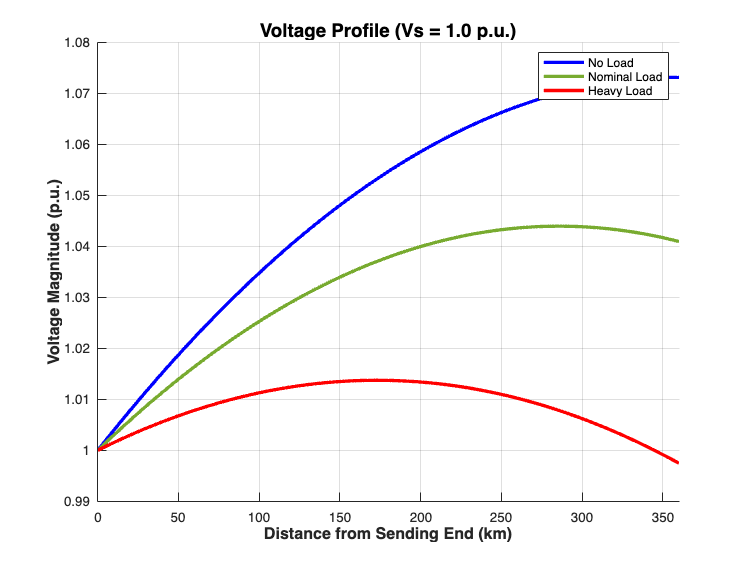

% Formatting Voltage Plot
set(0, 'CurrentFigure', ax1.Parent);
xlabel('Distance from Sending End (km)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Voltage Magnitude (p.u.)', 'FontSize', 12, 'FontWeight', 'bold');
title('Voltage Profile (Vs = 1.0 p.u.)', 'FontSize', 14);
legend('show');
xlim([0 L]);

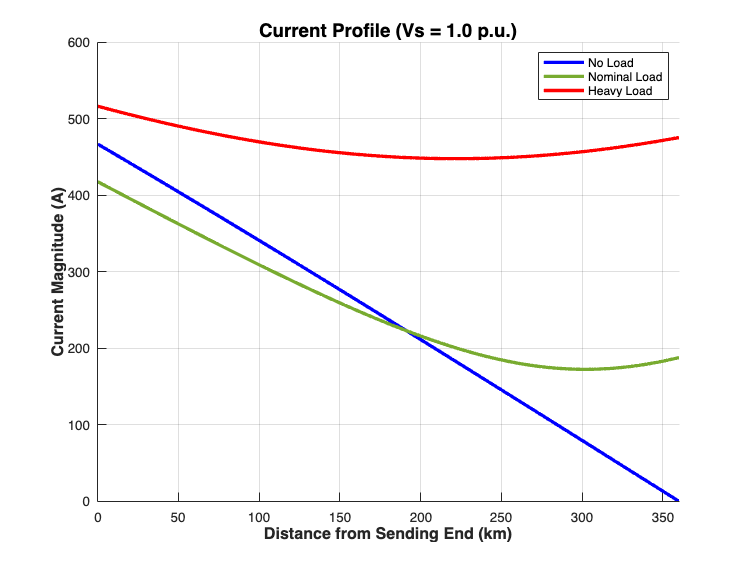

% Formatting Current Plot
set(0, 'CurrentFigure', ax2.Parent);
xlabel('Distance from Sending End (km)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Current Magnitude (A)', 'FontSize', 12, 'FontWeight', 'bold');
title('Current Profile (Vs = 1.0 p.u.)', 'FontSize', 14);
legend('show');
xlim([0 L]);